# Estimate of a mean

We have a theoretical model for the mean copy number of gene products in an ensemble of cells.  We assume the copy number in a given cell is proportional to the total fluorescence intensity of the cell.  Therefore, the pertinent statistic to calculate from a set of integrated intensities is the mean.

Our goal now is to acquire an estimate of the mean intensity of our collection of cells using the integrated intensities we got after performing the analysis in our image processing pipeline.  We will also get an estimate of our error of the mean.

First, we will load in the integrated intensities we have already computed using our newly found image processing skills.  The images used in this example were collected by Tal Einav at Caltech.

cd ~/git/mbl_physiology_matlab/gene_expression;
intensities = csvread('WT_dryrun_intensities.csv');

## Plot the ECDF

Let's take a quick look at the values to see what we are dealing with.  I find that the best way to investigate a set of measurments of this kind is to plot the **empirical cumulative distribution function** or ECDF.  Before defining the ECDF, it is useful to think about more generally what a **cumulative distribution function**, or CDF, is.  In the case of the intergrated intensities of our cells, the CDF, $F(I)$, is the probability that a randomly selected cell will have integrated intensity less than or equal to $I$. Generally,


$$F(x_0) = \text{probability that random variable } x\le x_0.$$


If the intensities, $I$, have probability distribution $P(I)$, then the cumulative distribution function, or CDF, is


$$F(I) = \int_{-\infty}^I \mathrm{d}I^\prime\,P(I^\prime) =  \int_{0}^I \mathrm{d}I^\prime\,P(I^\prime),$$


where the second equality in our case is because the intensities cannot be negative. As plotting a histogram of the data is a way of displaying the probability distribution, plotting the ECDF of the data is a way of displaying the CDF.  The advantage of the latter is that we do not have binning bias.

To plot the ECDF, we do the following steps.

- Set `x` to be the sorted data set.

- Set `y = (1:length(data)) / length(data)`.

- Plot `y` against `x`.

Let's take a look.

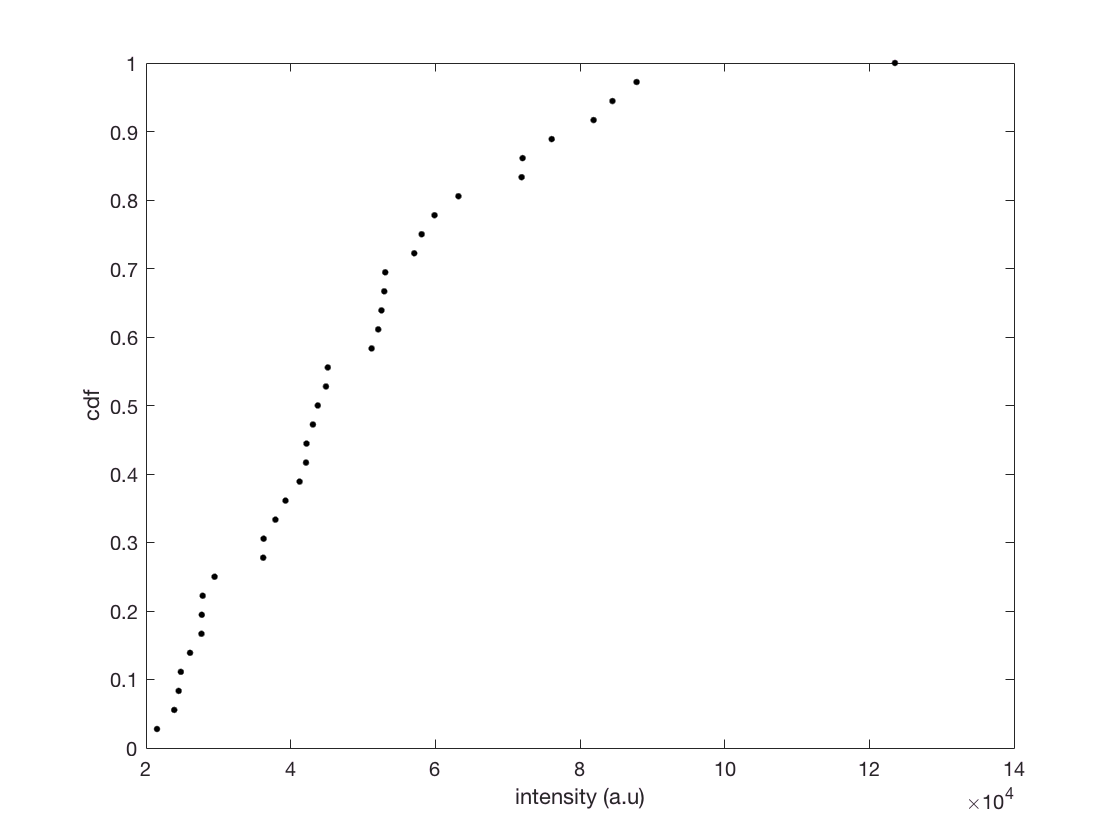

x = sort(intensities);
y = (1:length(intensities)) / length(intensities);
figure();
plot(x, y, 'k.', 'markersize', 20);
xlabel('intensity (a.u)');
ylabel('cdf');

Eyeballing the ECDF, the measured intensities range from about $2\times 10^{4}$ to $10^5$ with a mean of about $5\times10^5$ or so.  Importantly, we do not see any major outliers, such as values if intensity that are very low or very high.  We only have 36 samples, so we cannot really resolve the tail of the distribution, an issue we will address momentarily.

## Point estimate of the mean

The most important value we can calculate from the data may also seem like the most obvious: the mean.

meanIntensity = mean(intensities);
disp(meanIntensity)

   4.9544e+04



Indeed, our eyeball estimate was close.

## Bootstrap distribution of the mean

We have a point estimate for the mean, but how sure are we that the actual mean is given by this value?  To be more concrete, let $\bar{I}$ be the estimate of the mean we just calculated.  We want to know the probability distribution of $\bar{I}$, $P(\bar{I})$, which will help us know how confident we can be in our calculated mean intensity.  If the probability distribution is broad, we have less confidence in our computed mean, but if it is sharp, we have more confidence in our mean.

To estimate $P(\bar{I})$, we perform a **bootstrap estimate**.  Here is the basic idea.  Let $P(I)$be the (unknown) distribution function for the integrated fluorescence intensity.  We have measured intensities that come from this distribution.  We will therefore approximate $P(I)$ with its *empirical distribution*, $P^*(I)$.


$$P(I)\approx P^*(I) = n^{-1}\sum_{i=1}^n \delta(I-I_i),$$


where $\delta(x)$ denotes the Dirac delta function.  In practice, this means that we may only observe intensities that we have already observed.

We can **sample** out of this distribution.  This is akin to computationally repeating the experiment where we randomly draw intensities out of the empirical distribution.  From these samples, we then recompute the mean.  Such a sample is called a **bootstrap sample**. From sample to sample, the computed mean will vary, and this will give us an estimate of how much we expect the mean to vary if we were to repeat the experiment over and over again.  So, computing a bootstrap sample involved the following, assuming we have $n$ total intensities that we measured.

- Randomly select one of your measured intensities and store it.

- Repeat (1) until you have $n$ intensities. You do not remove a selected intensity from your list of measured intensities. You are *sampling with replacement*.

- Compute the mean of the intensities you just randomly selected. Store the result.

- Repeat steps (1)-(3) $B$ times to get $B$ bootstrap samples of the mean.

While pretty straightforward to code up, this procedure is done by Matlab's `bootstrp` function. In reading the documentation, `bootstrp` takes three arguments.  The first is $B$, the number of bootstrap samples to generate.  The second is a handle to the function that computes your test statistic.  In the procedure outlined above, we have computed the mean, but we could compute the median, variance, or any other arbitrary thing we wanted.  To use a function handle in Matlab, simple prepend the function name with an `@` symbol.  The final argument is your empirical data.

Let's now take 100,000 bootstrap samples of the mean.

bootMean = bootstrp(100000, @mean, intensities);

We now can plot the distribution of the mean as a histogram.

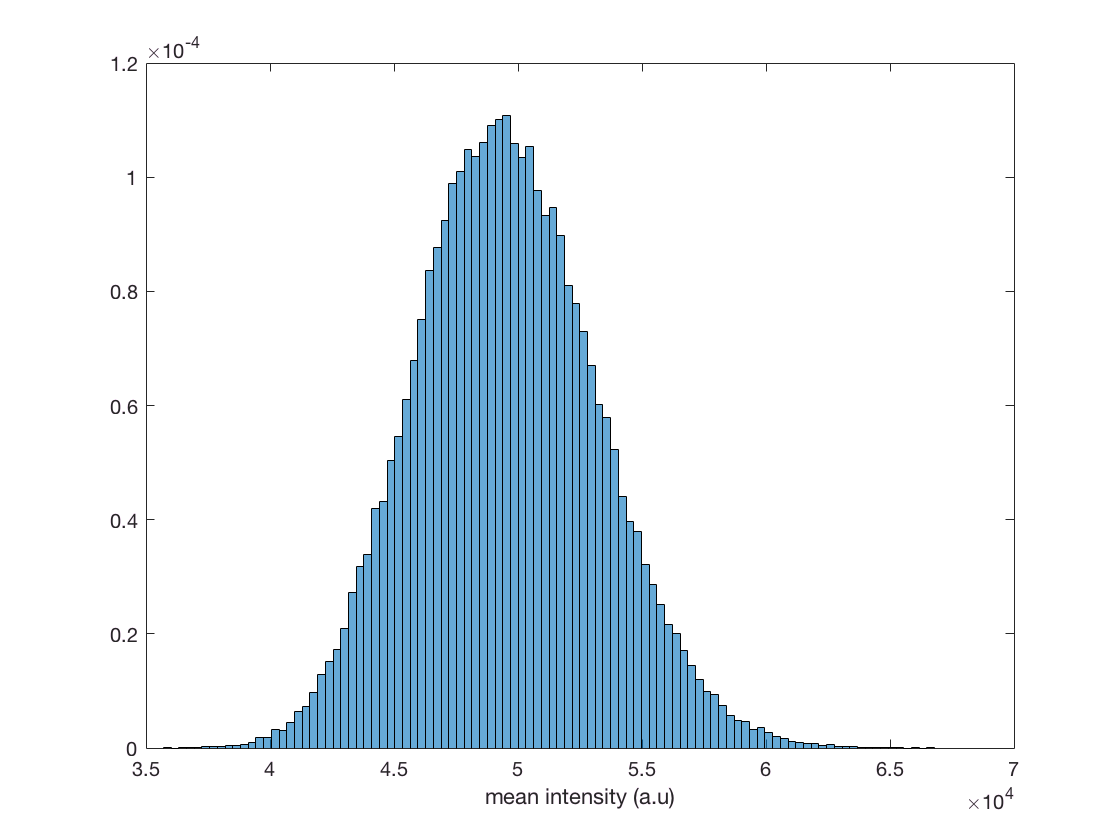

figure();
histogram(bootMean, 100, 'normalization', 'pdf');
xlabel('mean intensity (a.u)')

We can also plot a bootstrap CDF.

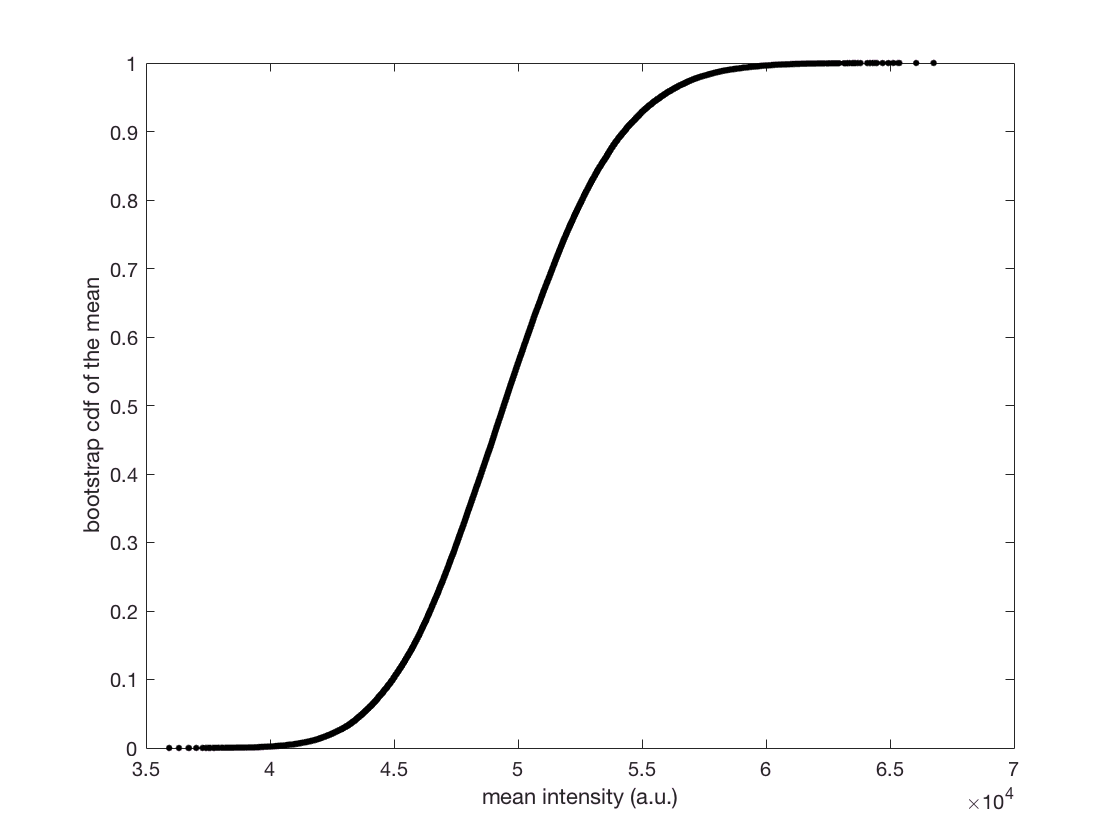

xBoot = sort(bootMean);
yBoot = (1:length(bootMean)) / length(bootMean);
plot(xBoot, yBoot, 'k.', 'markersize', 20);
xlabel('mean intensity (a.u.)');
ylabel('bootstrap cdf of the mean');

## Bootstrap confidence interval

From the histrogram and the boostrap CDF, we that more than 95% of the samples have a mean intensity that lies between about $4.5\times 10^4$ and $5.5\times 10^5$.  We can compute the 95% confidence interval more precisely using Matlab's `prctile` function.  Given an array, in our case `bootMean`, `prctile` computes percentiles.  To get a 95% confidence interval, we ask for the 2.5%-tile and 97.5%-tile values.

lowHigh = prctile(bootMean, [2.5, 97.5]);
disp(lowHigh);

   1.0e+04 *

    4.2740    5.6992



So, we have computed our estimate for the mean and the bootstrap confidence interval.  We report it like this: $4.95_{-0.68}^{+0.75}\times 10^4$ a.u.

## Gaussianity of the integrated intensities

In computing the mean and our bootstrap distribution and confidence interval, we have not assumed to know what the distrubution of intensities, $P(I)$, is. Depending on the dynamics of gene expression and the mechanisms by which it is regulated, $P(I)$ could take on several forms.  Working these out is beyond the scope of our current analysis. However, many of these forms are approximately Gaussian. We might like to know if our observed integrated intensities are commensurate with being Gaussian distributed.  If they are, we might assume Gaussianity, which will greatly simplify analysis going forward, particularly with regression.

How do we assess whether or not our observed data can be appropriately modeled as Gaussian? This is a subtle question, and there are many ways to approach it.  For our purposes, we will generate a **normal probability plot**, which is a way to graphically ascertain whether the data are Gaussian distributed or not.  To construct the plot, we compute **rankits**, which are the sorted values of $n$ draws from a standard normal distribution (Gaussian with zero mean and unit variance).  We then plot the sorted data versus the rankits.  If the data are Gaussian, this plot should be a straight line with a slope equal to the standard deviation of the data.  We can generate this plot using Matlab's `qqplot` function.

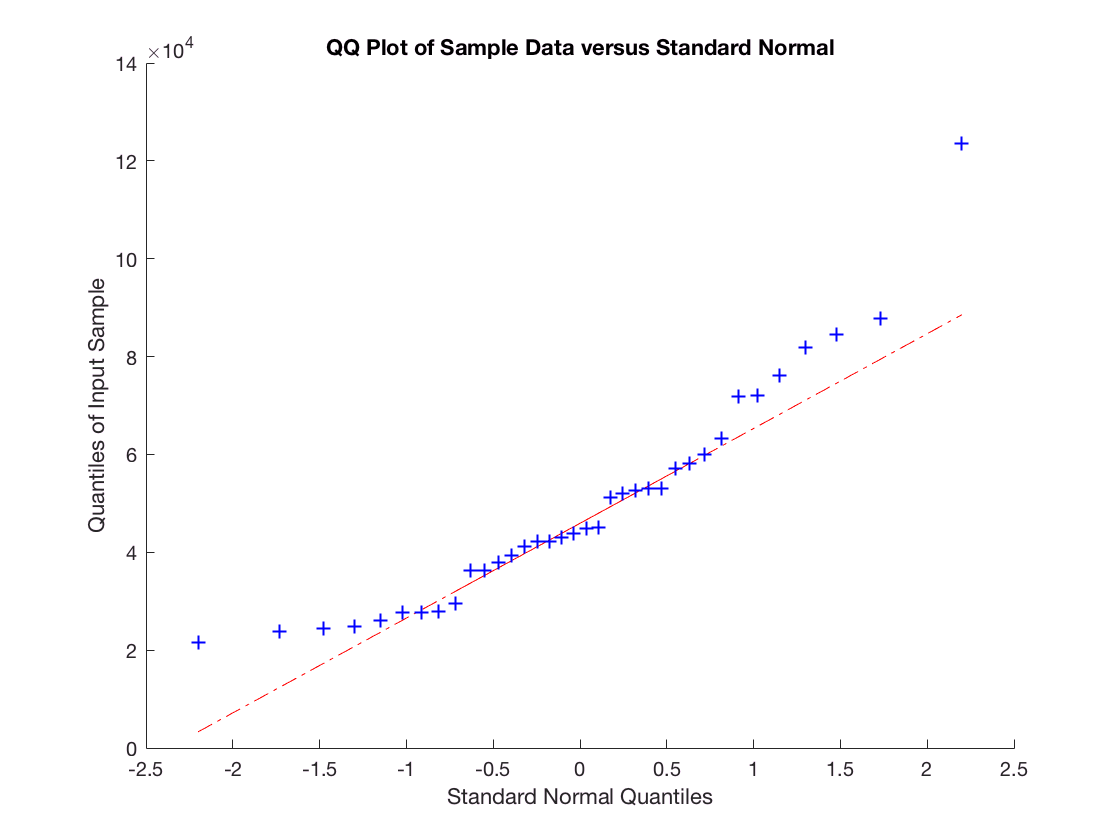

figure();
qqplot(intensities);

Qualitatively, the data seem to lie on the line, perhaps with some variability at the tails.  

The default plot from Matlab is an eyesore, and does not give us as good of a picture of Gaussianity as we would like.  We will therefore make our own normal probability plot.  We will generate 10,000 sets of rankits and then plot the 95% confidence intervals of the normal probability plot.  To generate the rankits, we just draw samples out of a normal distrubtion, which is accomplished with Matlab's `normrnd` function.  We then sort them, compute the percentiles, and then plot.

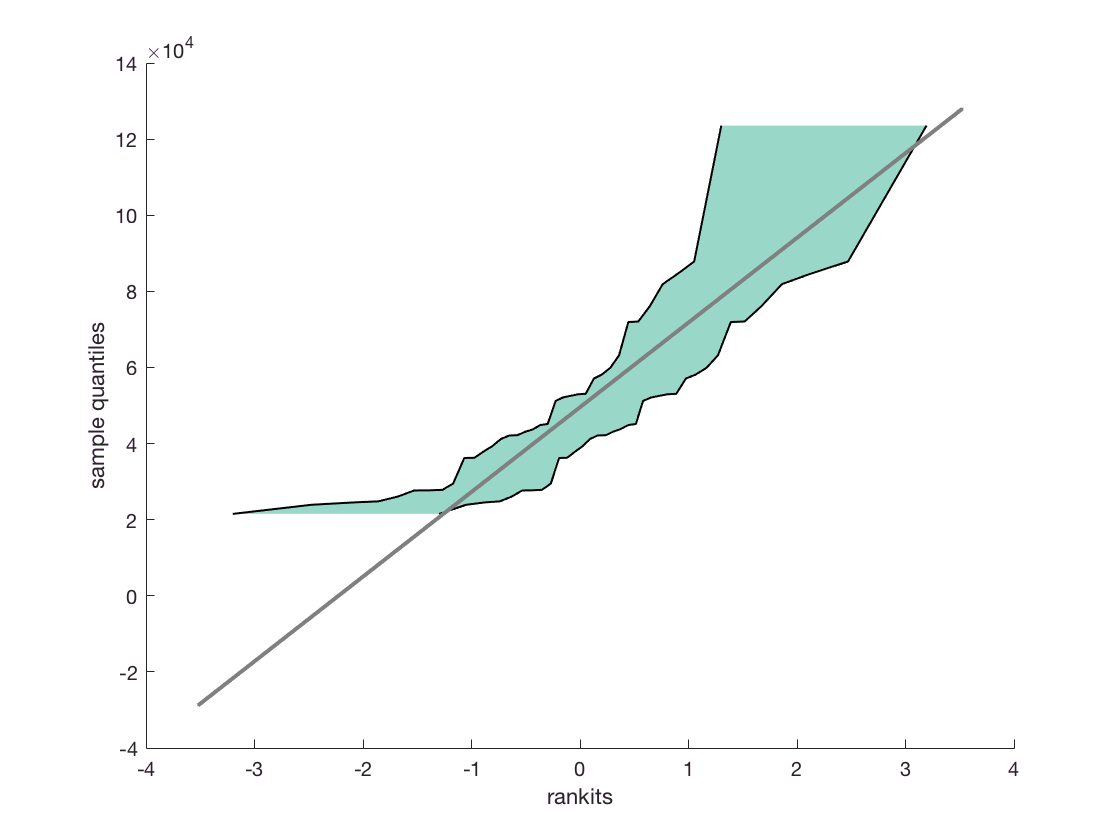

% Make rankits
rankits = sort(normrnd(0, 1, 10000, length(intensities)), 2);

% Determine confidence intervals
lowHigh = prctile(rankits, [2.5, 97.5], 1);
low = lowHigh(1,:);
high = lowHigh(2,:);

% Sort data and transpose so it is the right shape
z = sort(intensities)';

% Generate theoretical line
xlim = 1.1 * max([abs(low) ; abs(high)]);
x = [-xlim, xlim];
y = mean(z) + std(z) * x;

% Generate plots
figure();
hold on;
fill([high, fliplr(low)], [z, fliplr(z)], [153, 216, 201]/255, ...
     'linestyle', 'none');
plot(high, z, 'color', 'k', 'linewidth', 1);
plot(low, z, 'color', 'k', 'linewidth', 1);
plot(x, y, 'color', [0.5, 0.5, 0.5], 'linewidth', 2);
xlabel('rankits');
ylabel('sample quantiles');

Our much better looking plot also shows that Gaussianity falls within the 95% confidence interval.  So, we are emboldened to take $P(I)$ to be Gaussian.

## Gaussian confidence interval of the mean

Assuming that the data come from a Gaussian distribution (i.e., $P(I)$ is Gaussian), we know some things about the distribution of the mean, $P(\bar{I})$.  We actually know exactly what it is!  Though we will not derive it here, we know that $P(\bar{I})$ is a Gaussian whose mean is the mean of the measured intensities and whose variance is $s^2/n$, where $s^2$ is the estimator of the variance of the measured intensities,


$$s^2 = (n-1)^{-1}\sum_{i=1}^n(I_i-\bar{I})^2.$$


The square root of this variance is called the **standard error of the mean**.  We can then construct a confidence interval for the mean that encompasses 95% of the probability (or ±2 standard errors of the mean).

som = std(intensities) / sqrt(length(intensities));
disp(som)

   3.7093e+03



This gives a mean intensity of $(4.95 \pm 0.7)\times 10^{4}$ a.u., which is in line with our bootstrap estimate.

Let us now compare our bootstrap CDF for the mean with the Gaussian CDF for the mean.

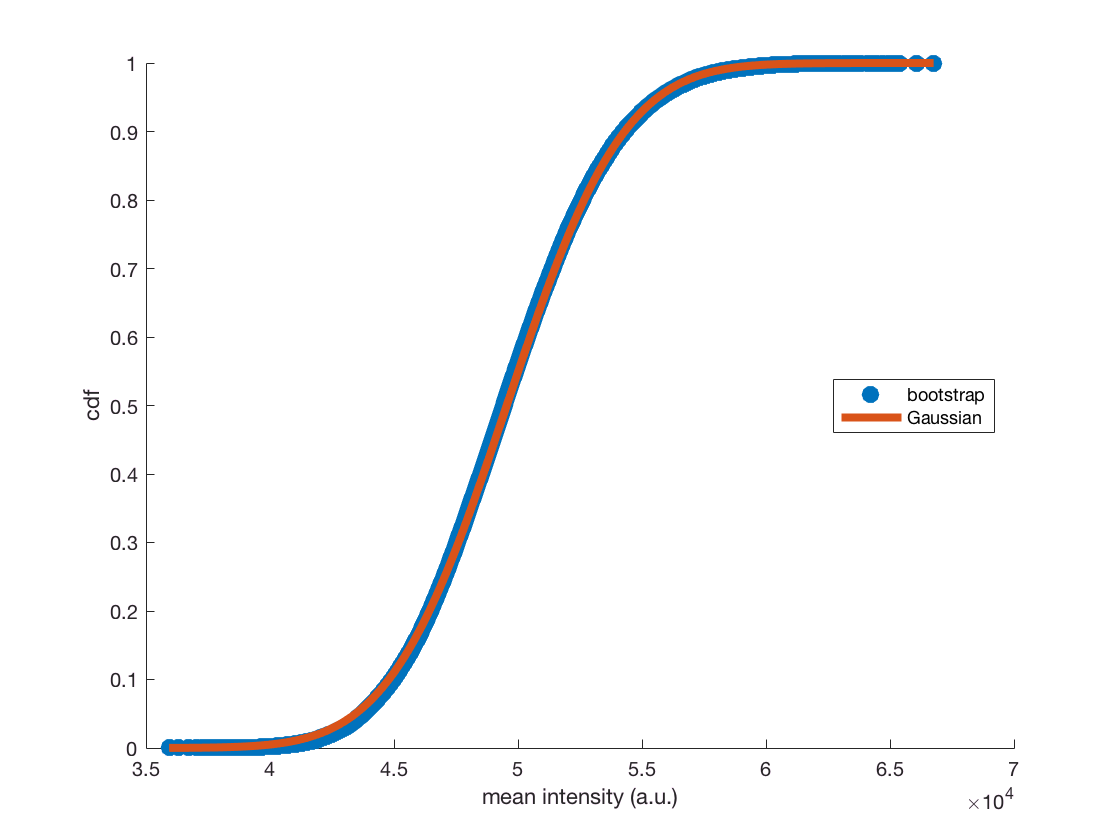

figure();
hold on;
xGauss = linspace(xBoot(1), xBoot(end), 400);
plot(xBoot, yBoot, '.', 'markersize', 30);
plot(xGauss, normcdf(xGauss, meanIntensity, som), 'linewidth', 4);
xlabel('mean intensity (a.u.)');
ylabel('cdf')
legend('bootstrap', 'Gaussian', 'location', 'east');

We see that they are in good agreement, so we will go ahead assuming the mean is Gaussian distributed with a standard deviation given by the standard error of the mean.

## Some further comments on the bootstrap, Gaussianity, and your computer

It was not actually a requirement that the distribution of integrated intensities be Gaussian in order for us to estimate the probability distribution of the mean intensity to be Gaussian, provided the varaince in the intensities is not enormous. This is a result of the **central limit theorem**.  This also means that we we did a bit more "work" than necessary in constructing our bootstrap estimate of the mean; we could have just used the stated analytical results.  Nonetheless, it was instructive to learn about bootstrapping and about normal probability plots.

Note that we did not *derive* the analytical results we used; I just stated them.  As your statistical models get more complicated, the analytical results become more and more difficult to derive.  However, your computer is a very powerful tool.  Because we can rapidly *sample* out of probability distributions, we can compute results we desire without the need to do often difficult (and approximate) analytical mathematics.

As an example, let's use the bootstrap to estimate the variance of fluorescence intensities. The point estimate is simple.

disp(var(intensities))

   4.9533e+08



But how confident are in in this estimate?  We can again use the bootstrap.

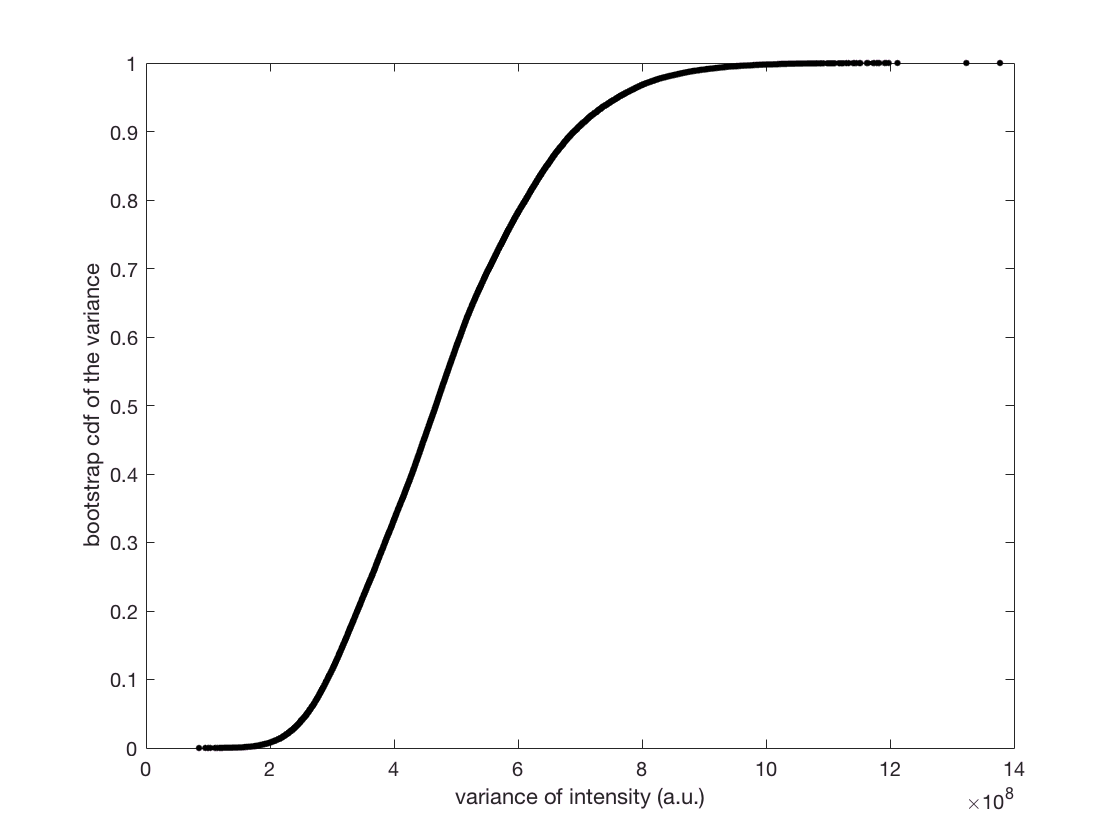

bootVar = bootstrp(100000, @var, intensities);
figure();
xBoot = sort(bootVar);
yBoot = (1:length(bootVar)) / length(bootVar);
plot(xBoot, yBoot, 'k.', 'markersize', 20);
xlabel('variance of intensity (a.u.)');
ylabel('bootstrap cdf of the variance');

The distribution is skewed a bit to the right, and we could also get confidence intervals for the variance.  We can do this for any statistic we would like to invent.  For fun, we'll do the median.

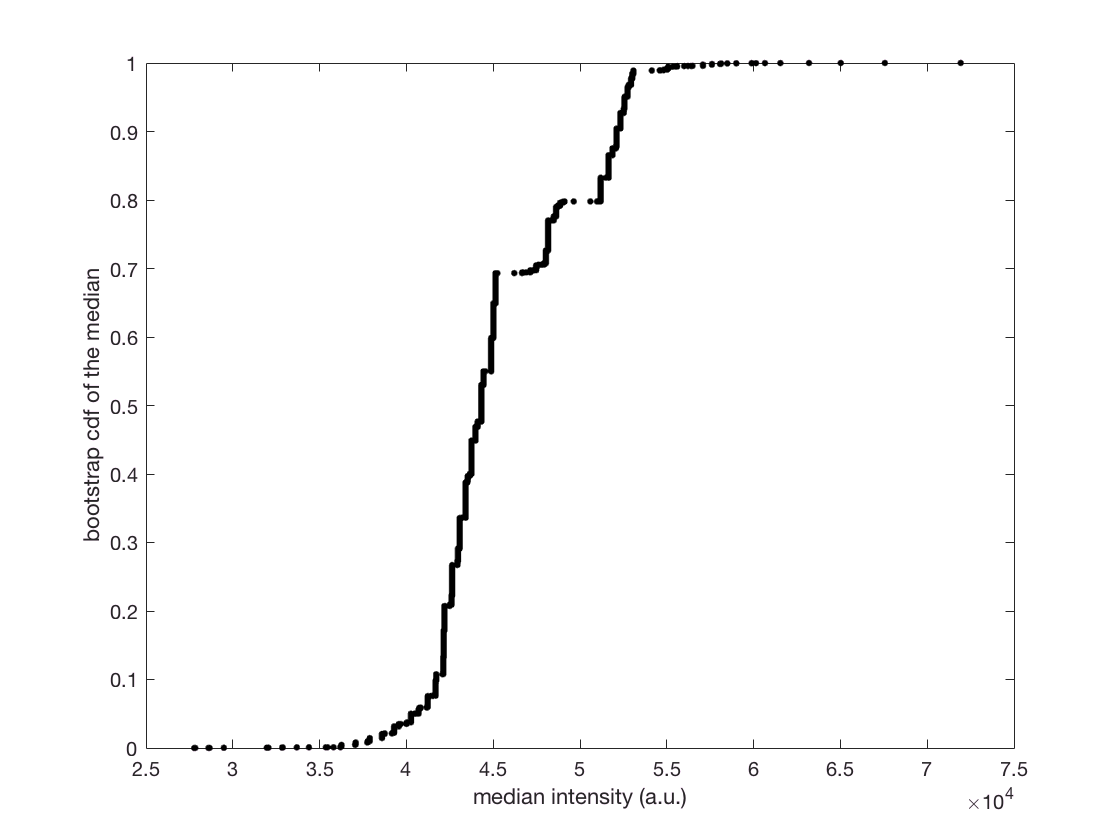

bootMed = bootstrp(100000, @median, intensities);
figure();
xBoot = sort(bootMed);
yBoot = (1:length(bootMed)) / length(bootMed);
plot(xBoot, yBoot, 'k.', 'markersize', 20);
xlabel('median intensity (a.u.)');
ylabel('bootstrap cdf of the median');